# Evaluate Object Detectors

Copyright 2018 The MathWorks, Inc.

## Load Ground Truth Data

Load the `gTruth` object from a saved MAT file. This dataset is different than the dataset used to train the detector. The ground truth is the set of known locations of objects of interest in a set of images to be used to validate the detectors

load('gTruthEvaluation.mat')

## Create Dataset from Ground Truth

Isolate ground truth data by their association with the '`bigRedBuoy`' label. This creates a new `gTruth` object that contains the ground truth of only the `bigRedBuoy`

redBuoyGTruth = selectLabels(gTruth,'bigRedBuoy');

Create a folder named `EvaluationData` in the current folder, if EvaluationData dosent exist, to store the training images and add to the path. Extract a subset of the Ground Truth dataset. `evaluationData `is a table that contains training data from the ground truth. This table can be used with the inbuilt evaluation functions like 

if ~isfolder(fullfile('EvaluationData'))
    
    mkdir EvaluationData
    addpath('EvaluationData');
    
    evaluationData = objectDetectorTrainingData(gTruth,...
    'SamplingFactor',1,'WriteLocation','EvaluationData');

end


Write images extracted for training to folder: 
    EvaluationData

Writing 100 images extracted from BuoyRun.avi...Completed.


Construct an Image Datastore 

imds = imageDatastore(fullfile('EvaluationData'));

Construct structure to store detection results

numImages = height(evaluationData);
result(numImages,:) = struct('Boxes',[],'Scores',[]);

## Process dataset to obtain detection results

for i = 1:numImages
    
    % Read Image
    I = readimage(imds,i); 
    
    % Detect the object of interest
    [bboxes, scores] = detect(detector,I,'Threshold',1);
    
    % Store result 
    result(i).Boxes = bboxes;
    result(i).Scores = scores;
   
end
% Convert structure to table
results = struct2table(result);

## Evaluate Detector

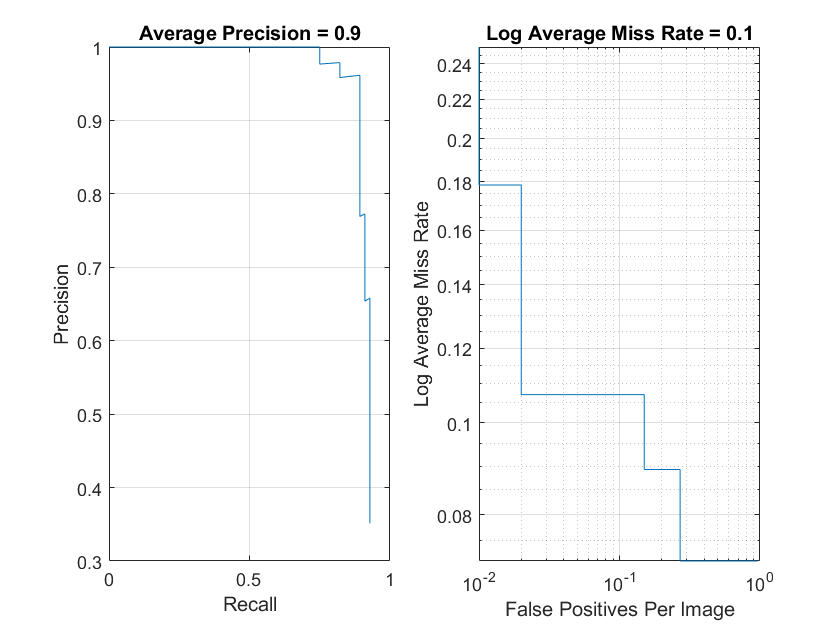

overlap = 0.5;
% Evaluate Metrics
[ap,recall,precision] = evaluateDetectionPrecision(results...
    ,evaluationData(:,3),overlap);

[am,fppi,missRate] = evaluateDetectionMissRate(results,evaluationData(:,3),overlap);

% Plot Metrics

subplot(1,2,1);
plot(recall,precision);
xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.1f', ap))
grid on

subplot(1,2,2);
loglog(fppi, missRate);
xlabel('False Positives Per Image');
ylabel('Log Average Miss Rate');
title(sprintf('Log Average Miss Rate = %.1f', am))
grid on

## Clean Up

rmpath('EvaluationData');